## Strong and Weak Scaling with a Small Problem Size 

Weak scaling here starts with a problem size of 2^28 and increases exponentially to over 17 billion trials of the Monte Carlo method. On the other hand, the large strong scaling problem set has a problem size of 2^30. Speedup, efficiency, and analysis of these larger datasets can be found below.

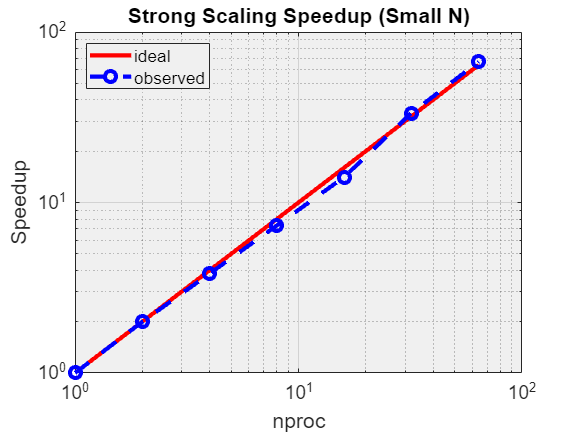

%Reading data
speedData=readmatrix('strongLarge.csv');
nproc=speedData(:,1);
time=speedData(:,2);
speedup = time(1)./time;
idealSpeedup = nproc;
%Speedup
loglog(nproc,idealSpeedup,'r-',nproc,speedup,'bo--','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Speedup','FontSize',14);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Strong Scaling Speedup (Small N)');
legend('ideal','observed','Location','northwest');

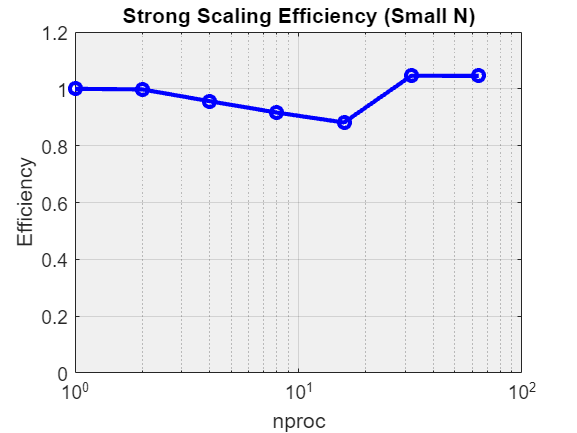


%Efficiency (Strong)
E = speedup./nproc;
semilogx(nproc,E,'bo-','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Efficiency','FontSize',14);
ylim([0 1.2]);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Strong Scaling Efficiency (Small N)');

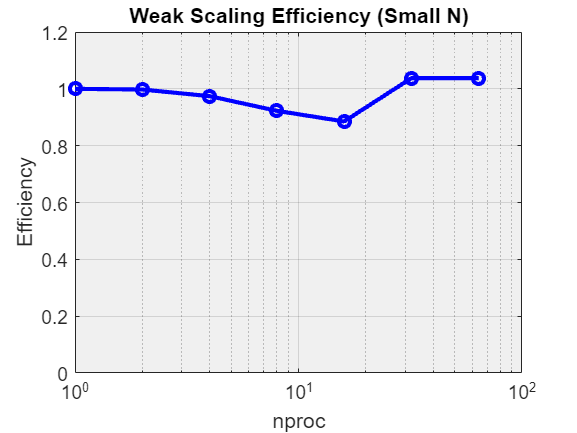


%Reading data
speedData=readmatrix('weakLarge.csv');
nproc=speedData(:,1);
time=speedData(:,2);
%Plotting
E=time(1)./time;
semilogx(nproc,E,'bo-','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Efficiency','FontSize',14);
ylim([0 1.2]);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Weak Scaling Efficiency (Small N)');

The speedup plot for strong scaling with this problem size shows incredible promise. As the number of processors grows, the speedup actually passes linear speedup which means that this program has extremely high parallel efficiency. This is demonstrated in the efficiency plot that, as displayed in the previous section regarding weak scaling with a small problem size, has over 100% efficiency. Again, this is impossible, but it goes to show the computing power multiple processors can have when tasked with a massive problem size. A nearly identical plot is mapped out under weak scaling efficiency, with consistent values close to 100% and for nproc=32,64 efficiency of over 100% again! This is more important in the weak scaling plot than in the strong scaling plot because it shows how scalable the program is. As the problem size grows, efficiency grows in close correlation with the number of processors! If this chart pattern were to continue, you could solve a problem of infinite size and only be limited by the compute power available. Parallel computing is meant to tackle problems of large magnitude, and the efficiency shown on these plots proves just that.